## Fully  constrained least square (FCLS)

### **On Salinas Data**

%Loading image
addpath('data');
image = load("Salinas_corrected.mat");
Salinas_Image = image.salinas_corrected;
% Get the dimensions of the Salinas_Image variable
[p1,n1,l]=size(Salinas_Image);
% Reshape the Salinas_Image variable into a 2D matrix of size (p1*n1, l)
X=reshape(Salinas_Image,p1*n1,l);
X=X';
%Loading ground truth image
gt = load("Salinas_gt.mat");
Salinas_Labels = gt.salinas_gt;
% Get the dimensions of the ground truth variable
[p2,n2]=size(Salinas_Labels);
y=reshape(Salinas_Labels,p2*n2,1);
y=y';
%Remove zero class labels

% Find the indices of the elements in the vector y that are equal to zero
zero_idx=find(~y);
% Find the indices of the elements in the vector y that are not equal to zero
nonzero_idx=find(y);
% Remove the columns of X and y corresponding to the zero indices
X(:,zero_idx)=[];
y(:,zero_idx)=[];

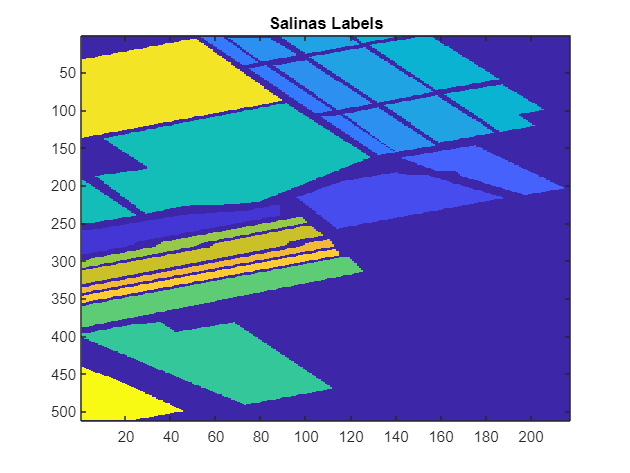

% Get the dimensions of the updated X matrix
[l,N]=size(X);
%% Visualizations %%
im=Salinas_Labels;
figure(1), imagesc(im);
title('Salinas Labels');
hold off

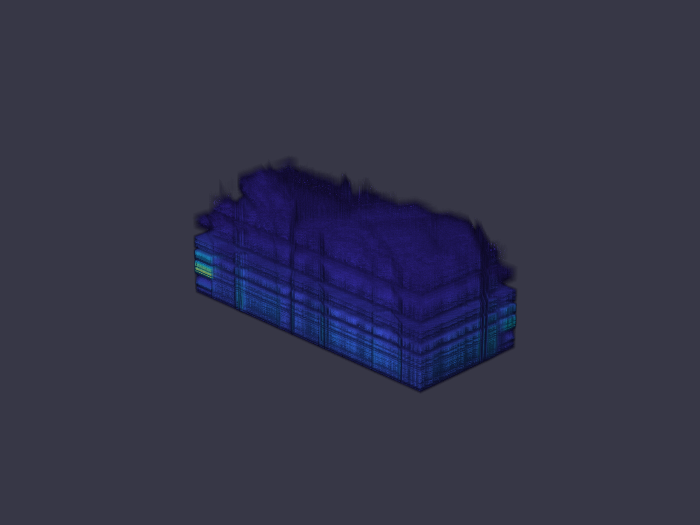

vol=Salinas_Image;
figure(2),volshow(vol,'Colormap',colormap);
hold off

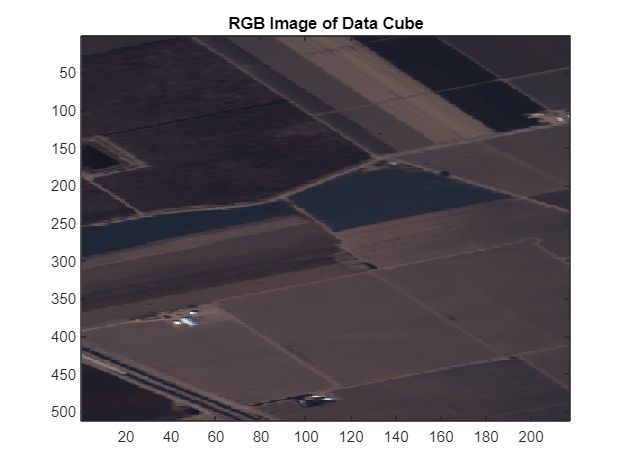

% Define the wavelength range and number of spectral bands
 % Minimum and maximum wavelengths
wavelengthRange = [400 2500];
% Number of spectral bands
numBands = 204;

% Create a vector of wavelengths that spans the specified range
wavelength = linspace(wavelengthRange(1),wavelengthRange(2),numBands);

% Create a hypercube object from the Salinas image data and wavelength vector
hcube = hypercube(Salinas_Image,wavelength);

% Convert the hypercube to an RGB image using a colorization method
rgbImg = colorize(hcube,'Method','RGB');

% Display the RGB image using the imagesc function
imagesc(rgbImg)
title('RGB Image of Data Cube')

prompt = "Number of endmembers to extract? ";
numEndmembers = input(prompt)

numEndmembers = 16

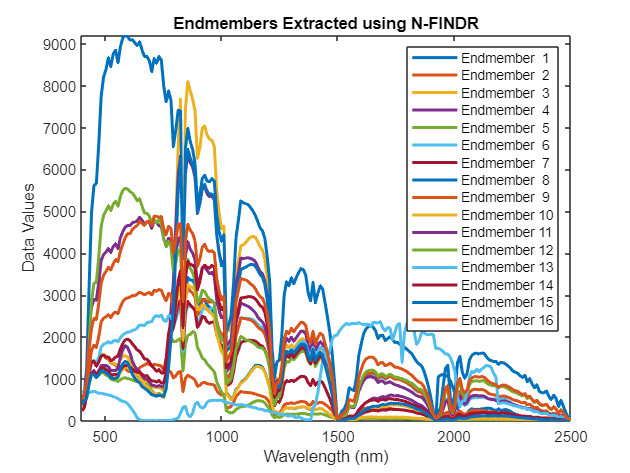

% Set the number of endmembers to extract using N-FINDR
%numEndmembers = 6;

% Use N-FINDR to extract the endmembers from the hypercube data
endMembers = nfindr(hcube.DataCube,numEndmembers);

% Plot the extracted endmembers as a function of wavelength
figure
plot(hcube.Wavelength,endMembers,'LineWidth',2)
axis tight
xlabel('Wavelength (nm)')
ylabel('Data Values')
title('Endmembers Extracted using N-FINDR')
num = 1:numEndmembers;
legendName = strcat('Endmember',{' '},num2str(num'));
legend(legendName)

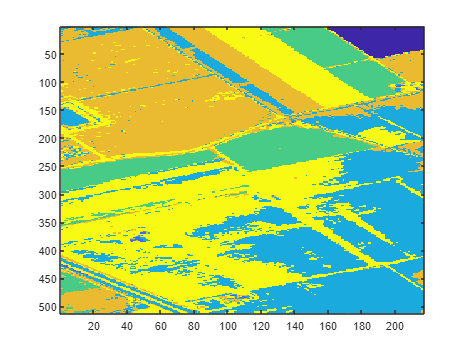

% Convert the hypercube data to a 2D matrix format
M=hyperConvert2d(hcube.DataCube);

% Use the fully constrained least squares (FCLS) algorithm to calculate the abundance maps
% for each endmember in the data
abundanceMaps = hyperFcls(M, endMembers);

% Convert the abundance maps back to a 3D matrix format
abundanceMaps = hyperConvert3d(abundanceMaps, 512, 217, 204);

% Find the index of the endmember with the highest abundance at each pixel location
[~,matchIdx] = max(abundanceMaps,[],3);
% Display the result as an image
figure
imagesc(matchIdx)

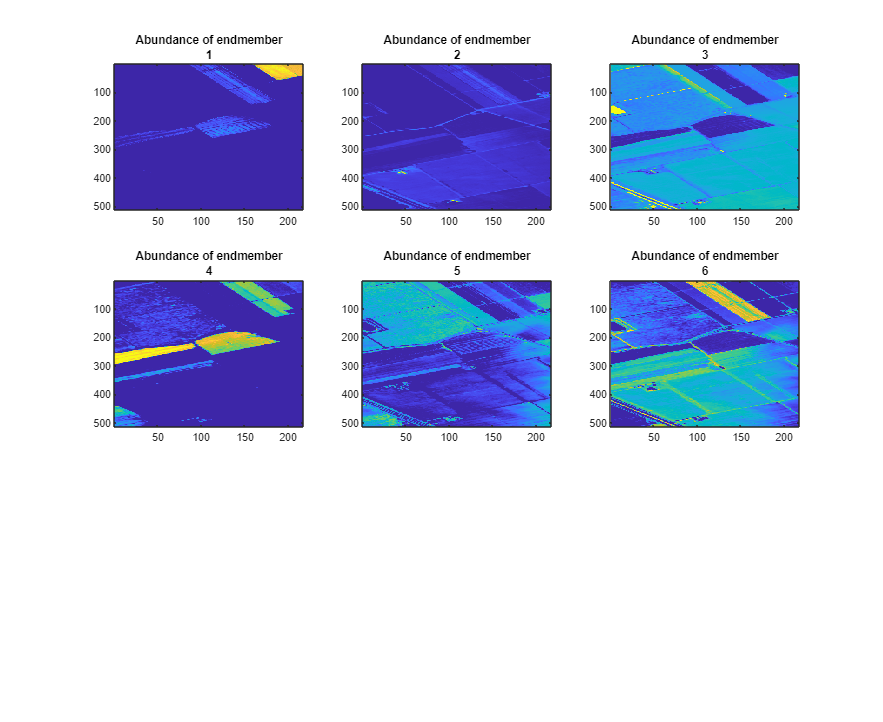

% Loop through each endmember and create a subplot with its abundance map
fig = figure('Position',[0 0 1100 900]);
n = ceil(sqrt(size(abundanceMaps,3)));
for cnt = 1:size(abundanceMaps,3)
    subplot(n,n,cnt)
    imagesc(abundanceMaps(:,:,cnt))
    title(['Abundance of endmember' {cnt}])
    hold on
end
hold off

### **On SalinasA Data**

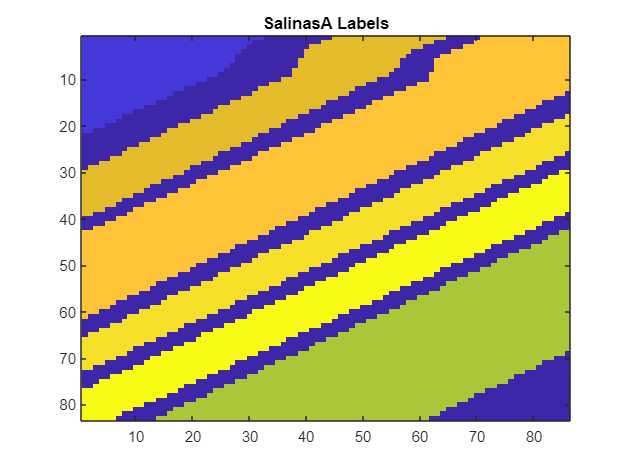

%Loading image
image = load("SalinasA_corrected.mat");
Salinas_Image = image.salinasA_corrected;
% Get the dimensions of the Salinas_Image variable
[p1,n1,l]=size(Salinas_Image);
% Reshape the Salinas_Image variable into a 2D matrix of size (p1*n1, l)
X=reshape(Salinas_Image,p1*n1,l);
X=X';
%Loading ground truth image
gt = load("SalinasA_gt.mat");
Salinas_Labels = gt.salinasA_gt;
% Get the dimensions of the ground truth variable
[p2,n2]=size(Salinas_Labels);
y=reshape(Salinas_Labels,p2*n2,1);
y=y';
%Remove zero class labels

% Find the indices of the elements in the vector y that are equal to zero
zero_idx=find(~y);
% Find the indices of the elements in the vector y that are not equal to zero
nonzero_idx=find(y);
% Remove the columns of X and y corresponding to the zero indices
X(:,zero_idx)=[];
y(:,zero_idx)=[];
% Get the dimensions of the updated X matrix
[l,N]=size(X);
%% Visualizations %%
im=Salinas_Labels;
figure(1), imagesc(im);
title('SalinasA Labels');
hold off

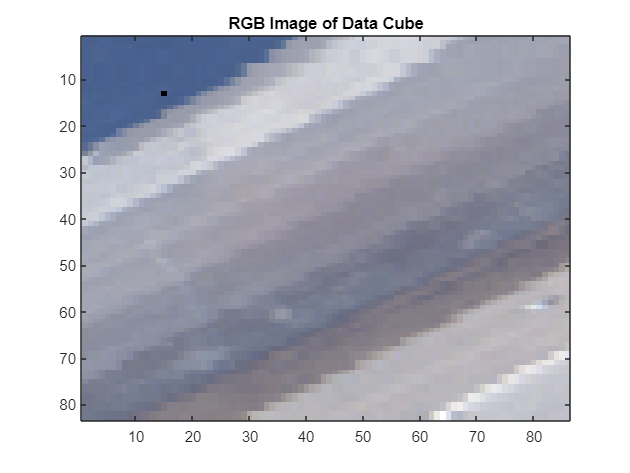

% Define the wavelength range and number of spectral bands
 % Minimum and maximum wavelengths
wavelengthRange = [400 2500];
% Number of spectral bands
numBands = 204;

% Create a vector of wavelengths that spans the specified range
wavelength = linspace(wavelengthRange(1),wavelengthRange(2),numBands);

% Create a hypercube object from the Salinas image data and wavelength vector
hcube = hypercube(Salinas_Image,wavelength);

% Convert the hypercube to an RGB image using a colorization method
rgbImg = colorize(hcube,'Method','RGB');

% Display the RGB image using the imagesc function
imagesc(rgbImg)
title('RGB Image of Data Cube')

prompt = "Number of endmembers to extract? ";
numEndmembers = input(prompt)

numEndmembers = 10

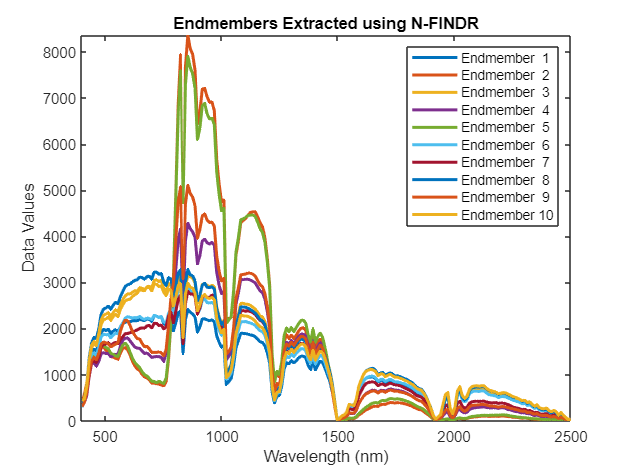

% Set the number of endmembers to extract using N-FINDR
%numEndmembers = 6;

% Use N-FINDR to extract the endmembers from the hypercube data
endMembers = nfindr(hcube.DataCube,numEndmembers);

% Plot the extracted endmembers as a function of wavelength
figure
plot(hcube.Wavelength,endMembers,'LineWidth',2)
axis tight
xlabel('Wavelength (nm)')
ylabel('Data Values')
title('Endmembers Extracted using N-FINDR')
num = 1:numEndmembers;
legendName = strcat('Endmember',{' '},num2str(num'));
legend(legendName)

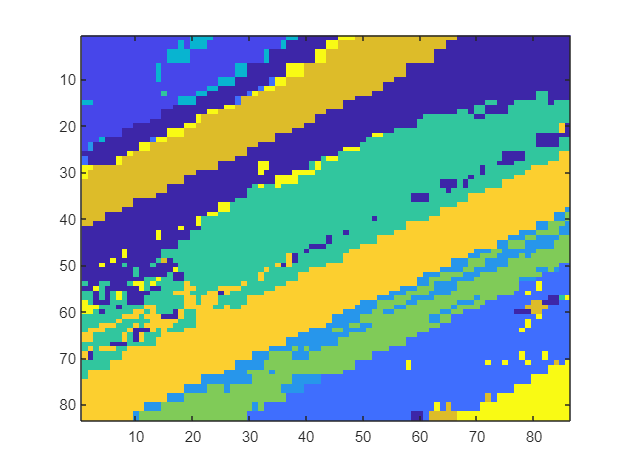

% Convert the hypercube data to a 2D matrix format
M=hyperConvert2d(hcube.DataCube);

% Use the fully constrained least squares (FCLS) algorithm to calculate the abundance maps
% for each endmember in the data
abundanceMaps = hyperFcls(M, endMembers);

% Convert the abundance maps back to a 3D matrix format
abundanceMaps = hyperConvert3d(abundanceMaps, 83, 86, 204);
% Find the index of the endmember with the highest abundance at each pixel location
[~,matchIdx] = max(abundanceMaps,[],3);
% Display the result as an image
figure
imagesc(matchIdx)

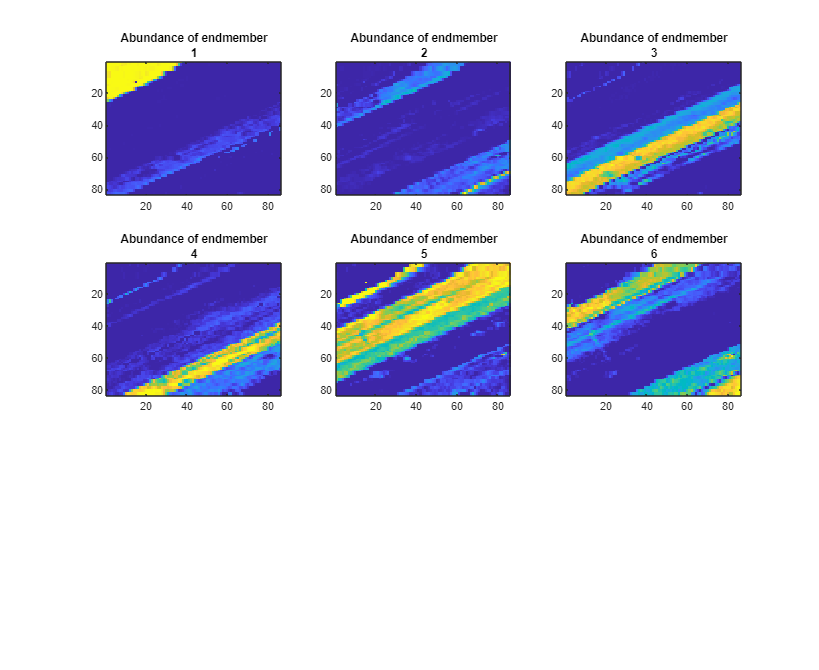

% Loop through each endmember and create a subplot with its abundance map
fig = figure('Position',[0 0 1100 900]);
n = ceil(sqrt(size(abundanceMaps,3)));
for cnt = 1:size(abundanceMaps,3)
    subplot(n,n,cnt)
    imagesc(abundanceMaps(:,:,cnt))
    title(['Abundance of endmember' {cnt}])
    hold on
end
hold off

### **On Indian Pines Data**

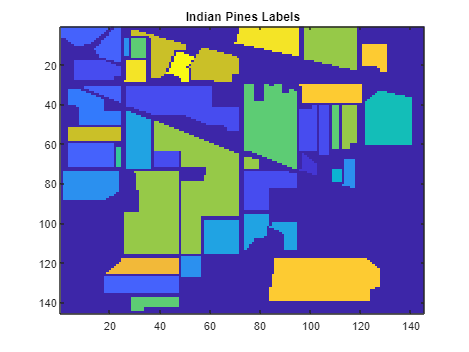

%Loading image
image = load("Indian_pines_corrected.mat");
Salinas_Image = image.indian_pines_corrected;
% Get the dimensions of the Salinas_Image variable
[p1,n1,l]=size(Salinas_Image);
% Reshape the Salinas_Image variable into a 2D matrix of size (p1*n1, l)
X=reshape(Salinas_Image,p1*n1,l);
X=X';
%Loading ground truth image
gt = load("Indian_pines_gt.mat");
Salinas_Labels = gt.indian_pines_gt;
% Get the dimensions of the ground truth variable
[p2,n2]=size(Salinas_Labels);
y=reshape(Salinas_Labels,p2*n2,1);
y=y';
%Remove zero class labels

% Find the indices of the elements in the vector y that are equal to zero
zero_idx=find(~y);
% Find the indices of the elements in the vector y that are not equal to zero
nonzero_idx=find(y);
% Remove the columns of X and y corresponding to the zero indices
X(:,zero_idx)=[];
y(:,zero_idx)=[];
% Get the dimensions of the updated X matrix
[l,N]=size(X);
%% Visualizations %%
im=Salinas_Labels;
figure(1), imagesc(im);
title('Indian Pines Labels');
hold off

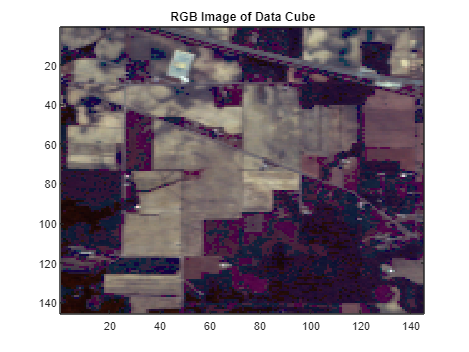

% Define the wavelength range and number of spectral bands
 % Minimum and maximum wavelengths
wavelengthRange = [380 2000];
% Number of spectral bands
numBands = 200;

% Create a vector of wavelengths that spans the specified range
wavelength = linspace(wavelengthRange(1),wavelengthRange(2),numBands);

% Create a hypercube object from the Salinas image data and wavelength vector
hcube = hypercube(Salinas_Image,wavelength);

% Convert the hypercube to an RGB image using a colorization method
rgbImg = colorize(hcube,'Method','RGB');

% Display the RGB image using the imagesc function
imagesc(rgbImg)
title('RGB Image of Data Cube')

prompt = "Number of endmembers to extract? ";
numEndmembers = input(prompt)

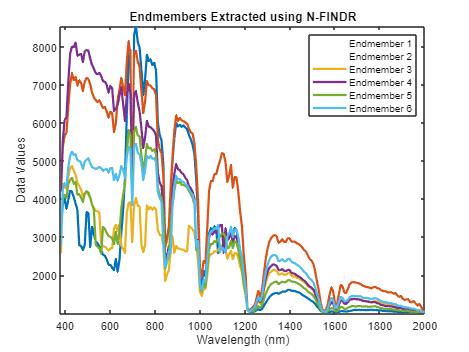

% Set the number of endmembers to extract using N-FINDR
%numEndmembers = 6;

% Use N-FINDR to extract the endmembers from the hypercube data
endMembers = nfindr(hcube.DataCube,numEndmembers);

% Plot the extracted endmembers as a function of wavelength
figure
plot(hcube.Wavelength,endMembers,'LineWidth',2)
axis tight
xlabel('Wavelength (nm)')
ylabel('Data Values')
title('Endmembers Extracted using N-FINDR')
num = 1:numEndmembers;
legendName = strcat('Endmember',{' '},num2str(num'));
legend(legendName)

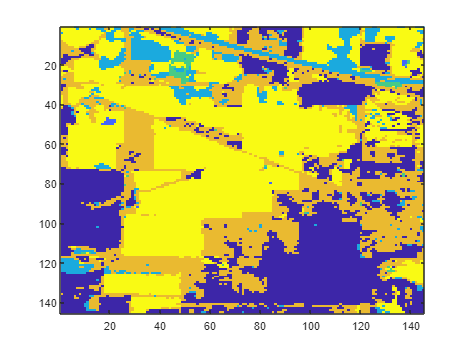

% Convert the hypercube data to a 2D matrix format
M=hyperConvert2d(hcube.DataCube);

% Use the fully constrained least squares (FCLS) algorithm to calculate the abundance maps
% for each endmember in the data
abundanceMaps = hyperFcls(M, endMembers);

% Convert the abundance maps back to a 3D matrix format
abundanceMaps = hyperConvert3d(abundanceMaps, 145, 145, 200);

% Find the index of the endmember with the highest abundance at each pixel location
[~,matchIdx] = max(abundanceMaps,[],3);
% Display the result as an image
figure
imagesc(matchIdx)

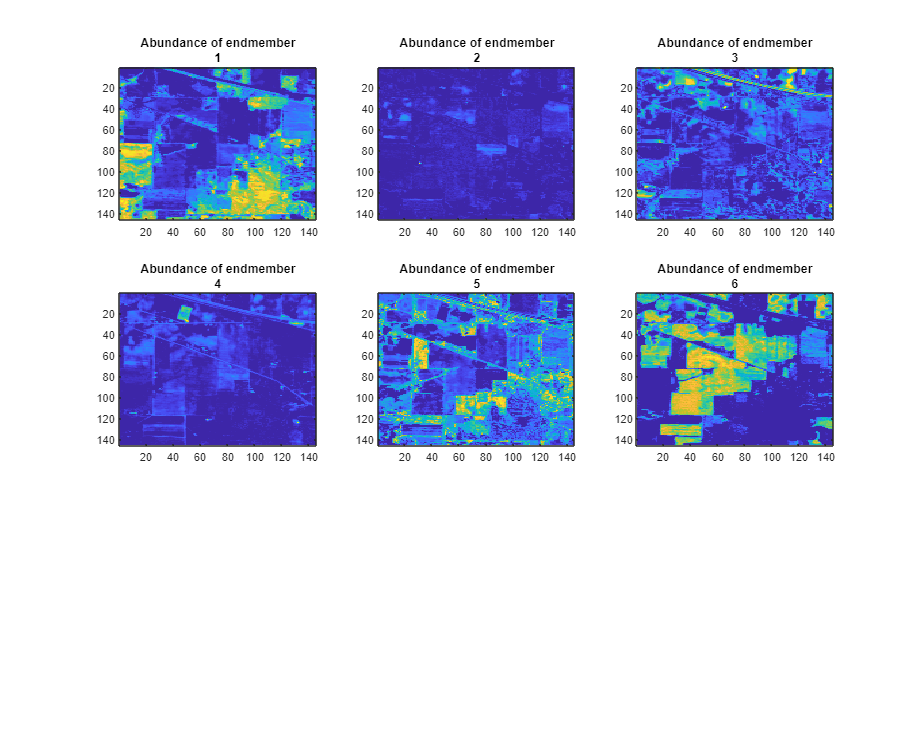

% Loop through each endmember and create a subplot with its abundance map
fig = figure('Position',[0 0 1100 900]);
n = ceil(sqrt(size(abundanceMaps,3)));
for cnt = 1:size(abundanceMaps,3)
    subplot(n,n,cnt)
    imagesc(abundanceMaps(:,:,cnt))
    title(['Abundance of endmember' {cnt}])
    hold on
end
hold off

### **On Kennedy Space Center (KSC) Data**

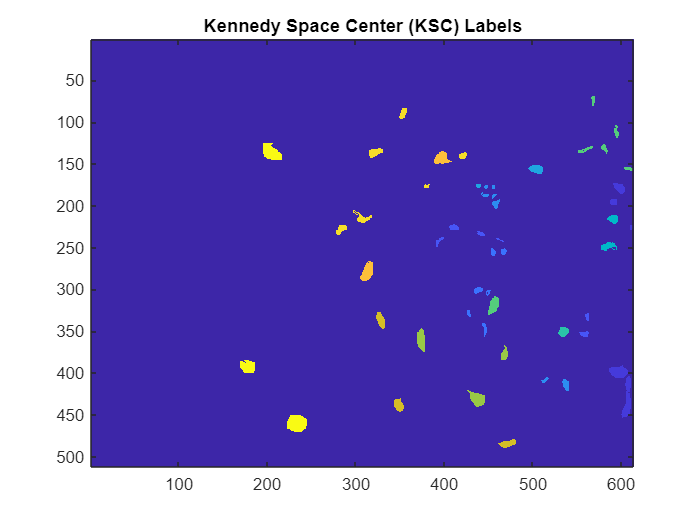

%Loading image
image = load("KSC.mat");
Salinas_Image = image.KSC;
% Get the dimensions of the Salinas_Image variable
[p1,n1,l]=size(Salinas_Image);
% Reshape the Salinas_Image variable into a 2D matrix of size (p1*n1, l)
X=reshape(Salinas_Image,p1*n1,l);
X=X';
%Loading ground truth image
gt = load("KSC_gt.mat");
Salinas_Labels = gt.KSC_gt;
% Get the dimensions of the ground truth variable
[p2,n2]=size(Salinas_Labels);
y=reshape(Salinas_Labels,p2*n2,1);
y=y';
%Remove zero class labels

% Find the indices of the elements in the vector y that are equal to zero
zero_idx=find(~y);
% Find the indices of the elements in the vector y that are not equal to zero
nonzero_idx=find(y);
% Remove the columns of X and y corresponding to the zero indices
X(:,zero_idx)=[];
y(:,zero_idx)=[];
% Get the dimensions of the updated X matrix
[l,N]=size(X);
%% Visualizations %%
im=Salinas_Labels;
figure(1), imagesc(im);
title('Kennedy Space Center (KSC) Labels');
hold off

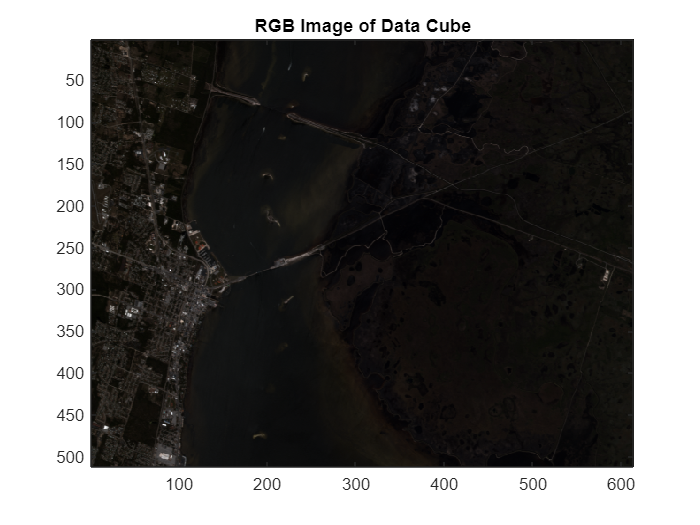

% Define the wavelength range and number of spectral bands
 % Minimum and maximum wavelengths
wavelengthRange = [400 2500];
% Number of spectral bands
numBands = 176;

% Create a vector of wavelengths that spans the specified range
wavelength = linspace(wavelengthRange(1),wavelengthRange(2),numBands);

% Create a hypercube object from the Salinas image data and wavelength vector
hcube = hypercube(Salinas_Image,wavelength);

% Convert the hypercube to an RGB image using a colorization method
rgbImg = colorize(hcube,'Method','RGB');

% Display the RGB image using the imagesc function
imagesc(rgbImg)
title('RGB Image of Data Cube')

prompt = "Number of endmembers to extract? ";
numEndmembers = input(prompt)

numEndmembers = 16

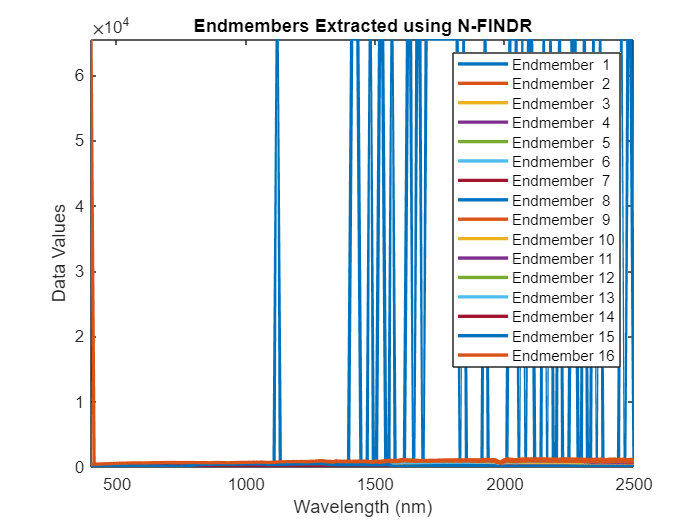

% Set the number of endmembers to extract using N-FINDR
%numEndmembers = 6;

% Use N-FINDR to extract the endmembers from the hypercube data
endMembers = nfindr(hcube.DataCube,numEndmembers);

% Plot the extracted endmembers as a function of wavelength
figure
plot(hcube.Wavelength,endMembers,'LineWidth',2)
axis tight
xlabel('Wavelength (nm)')
ylabel('Data Values')
title('Endmembers Extracted using N-FINDR')
num = 1:numEndmembers;
legendName = strcat('Endmember',{' '},num2str(num'));
legend(legendName)

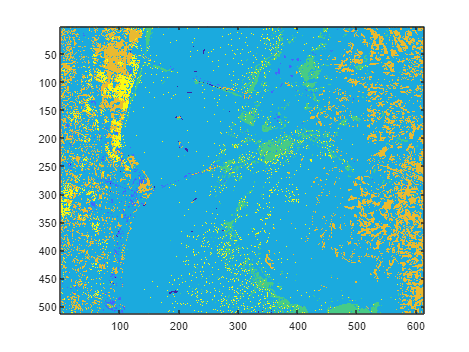

% Convert the hypercube data to a 2D matrix format
M=hyperConvert2d(hcube.DataCube);

% Use the fully constrained least squares (FCLS) algorithm to calculate the abundance maps
% for each endmember in the data
abundanceMaps = hyperFcls(M, endMembers);

% Convert the abundance maps back to a 3D matrix format
abundanceMaps = hyperConvert3d(abundanceMaps, 512, 614, 176);

% Find the index of the endmember with the highest abundance at each pixel location
[~,matchIdx] = max(abundanceMaps,[],3);
% Display the result as an image
figure
imagesc(matchIdx)

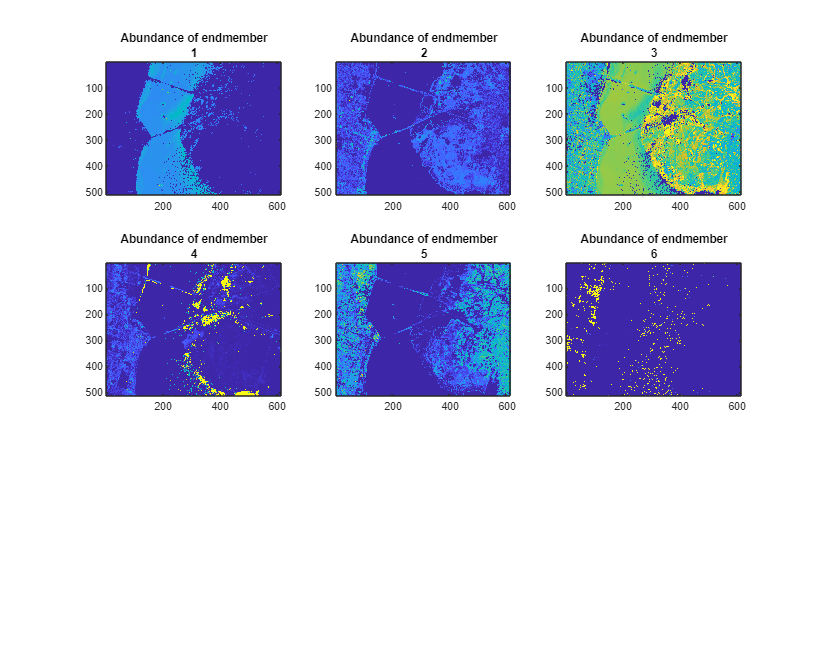

% Loop through each endmember and create a subplot with its abundance map
fig = figure('Position',[0 0 1100 900]);
n = ceil(sqrt(size(abundanceMaps,3)));
for cnt = 1:size(abundanceMaps,3)
    subplot(n,n,cnt)
    imagesc(abundanceMaps(:,:,cnt))
    title(['Abundance of endmember' {cnt}])
    hold on
end
hold off

function [M] = hyperConvert2d(M)
% HYPERCONVERT2D Converts an HSI cube to a 2D matrix
% Converts a 3D HSI cube (m x n x p) to a 2D matrix of points (p X N)
% where N = mn
%
% Usage
%   [M] = hyperConvert2d(M)
% Inputs
%   M - 3D HSI cube (m x n x p)
% Outputs
%   M - 2D data matrix (p x N)

% Check if input image has the correct dimensions (either 2D or 3D)
% If it has more than 3 dimensions or less than 2 dimensions, throw an error.
if (ndims(M)>3 || ndims(M)<2)
    error('Input image must be m x n x p or m x n');
end

% If input image is 2D, set number of bands to 1 and get the dimensions of the
% image. If input image is 3D, get the dimensions of the image and the number 
% of spectral bands.

% Reshape the 3D image into a 2D matrix
if (ndims(M) == 2)
    numBands = 1;
    [h, w] = size(M);
else
    [h, w, numBands] = size(M);
end

M = reshape(M, w*h, numBands).';
end



function [img] = hyperConvert3d(img, h, w, numBands)
% HYPERCONVERT2D Converts an 2D matrix to a 3D data cube
% Converts a 2D matrix (p x N) to a 3D data cube (m x n x p)
% where N = m * n
% 
% Usage
%   [M] = hyperConvert3d(M)
% Inputs
%   M - 2D data matrix (p x N)
% Outputs
%   M - 3D data cube (m x n x p)


% Check if input matrix has the correct dimensions (2D)
% If it has more than 2 dimensions or less than 2 dimensions, throw an error.
if (ndims(img) ~= 2)
    error('Input image must be p x N.');
end

% Get the number of spectral bands and the total number of pixels in the image
[numBands, N] = size(img);

% If the number of pixels is 1, reshape the 2D matrix into a 2D image. 
% If the number of pixels is greater than 1, reshape the 2D matrix into a
% 3D hyperspectral data cube.
if (1 == N)
    img = reshape(img, h, w);
else
    img = reshape(img.', h, w, numBands); 
end

end



function [ X ] = hyperFcls( M, U )
%HYPERFCLS Performs fully constrained least squares on pixels of M.
% hyperFcls performs fully constrained least squares of each pixel in M 
% using the endmember signatures of U.  Fully constrained least squares 
% is least squares with the abundance sum-to-one constraint (ASC) and the 
% abundance nonnegative constraint (ANC).
%
% Usage
%   [ X ] = hyperFcls( M, U )
% Inputs
%   M - HSI data matrix (p x N)
%   U - Matrix of endmembers (p x q)
% Outputs
%   X - Abundance maps (q x N)
%
% References
%   "Fully Constrained Least-Squares Based Linear Unmixing." Daniel Heinz, 
% Chein-I Chang, and Mark L.G. Althouse. IEEE. 1999.

if (ndims(U) ~= 2)
    error('M must be a p x q matrix.');
end

[p1, N] = size(M);
[p2, q] = size(U);
if (p1 ~= p2)
    error('M and U must have the same number of spectral bands.');
end

p = p1;
X = zeros(q, N);
Mbckp = U;
for n1 = 1:N
    count = q;
    done = 0;
    ref = 1:q;
    r = M(:, n1);
    U = Mbckp;

     % Loop until all abundances are non-negative
    while not(done)

        % Compute abundance estimate
        als_hat = inv(U.'*U)*U.'*r;
        % Compute scaling factor
        s = inv(U.'*U)*ones(count, 1);

        afcls_hat = als_hat - inv(U.'*U)*ones(count, 1)*inv(ones(1, count)*inv(U.'*U)*ones(count, 1))*(ones(1, count)*als_hat-1);

        % See if all components are positive.  If so, then stop.
        if (sum(afcls_hat>0) == count)
            alpha = zeros(q, 1);
            alpha(ref) = afcls_hat;
            break;
        end
        % Multiply negative elements by their counterpart in the s vector.
        % Find largest abs(a_ij, s_ij) and remove entry from alpha.
        idx = find(afcls_hat<0);
        afcls_hat(idx) = afcls_hat(idx) ./ s(idx);
        [val, maxIdx] = max(abs(afcls_hat(idx)));
        maxIdx = idx(maxIdx);
        alpha(maxIdx) = 0;
        keep = setdiff(1:size(U, 2), maxIdx);
        U = U(:, keep);
        count = count - 1;
        ref = ref(keep);
    end
    X(:, n1) = alpha;
end
end